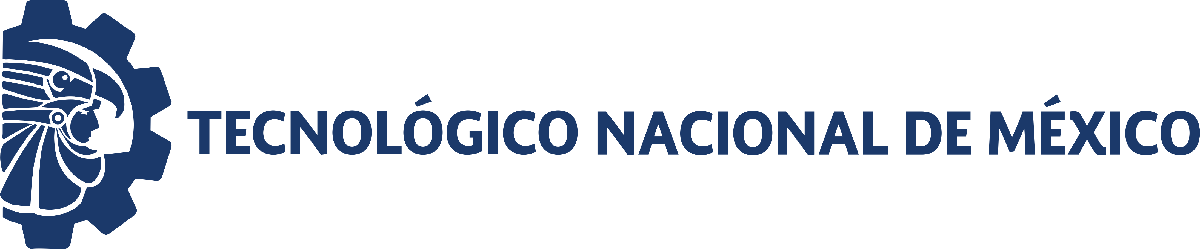                                 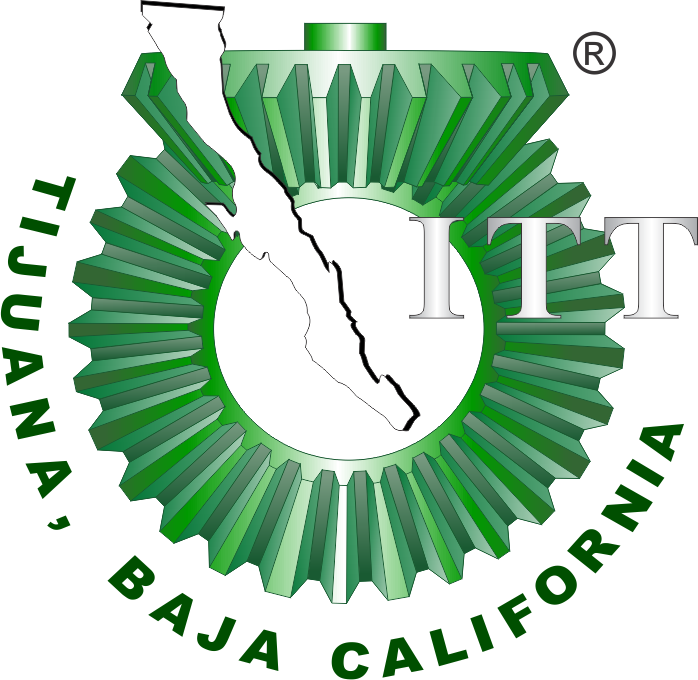

# Práctica cuatro:  Sistema endocrino

**Departamento de Ingeniería Eléctrica y Electrónica, Ingeniería Biomédica**

**Tecnológico Nacional de México [TecNM - Tijuana], Blvd. Alberto Limón Padilla s/n, C.P. 22454, Tijuana, B.C., México**

## Información general

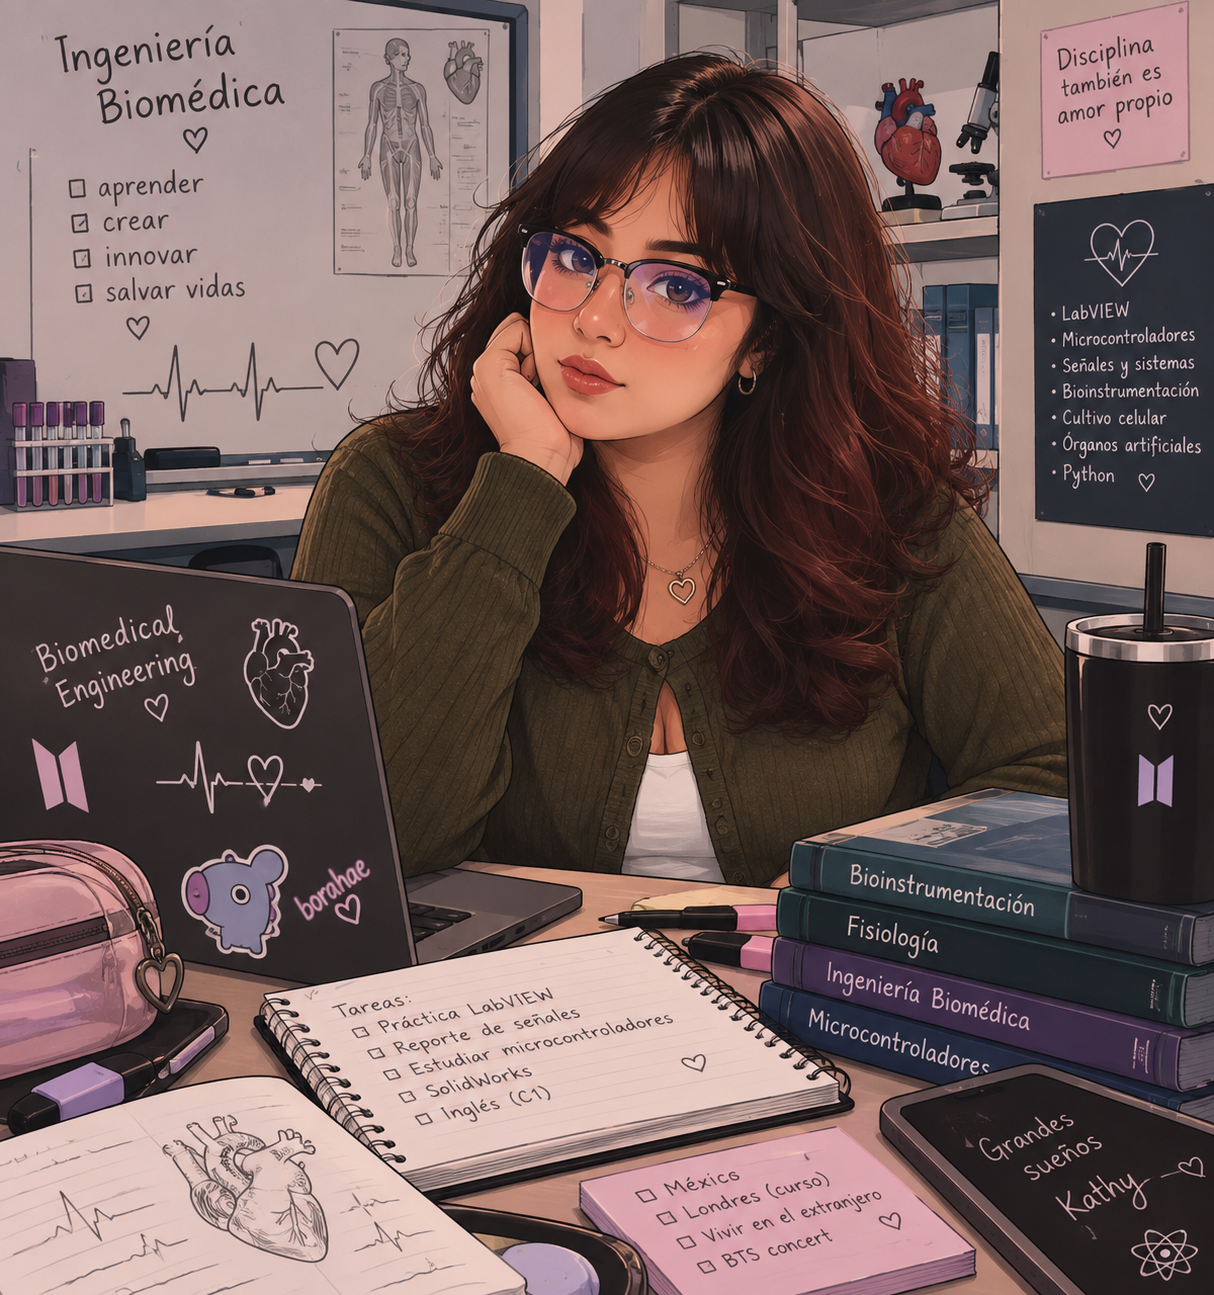

Nombre del alumno: Katherine Coria Camacho

Número de control: 23212189

Correo institucional: l23212189**@tectijuana.edu.mx**

Asignatura: **Modelado de Sistemas Fisiológicos**

Docente: **Dr. Paul Antonio Valle Trujillo; paul.valle@tectijuana.edu.mx**

## Datos de la simulación

clc; clear; close all; warning('off','all')
open_system('sistema5.slx')
close_system('sistema5/Scope',0);
parameters.StopTime= '15';
parameters.Solver = 'ode15s';
parameters.MaxStep = ' 1e-2';
x = sim('sistema5',parameters);


## Respuesta caso y control

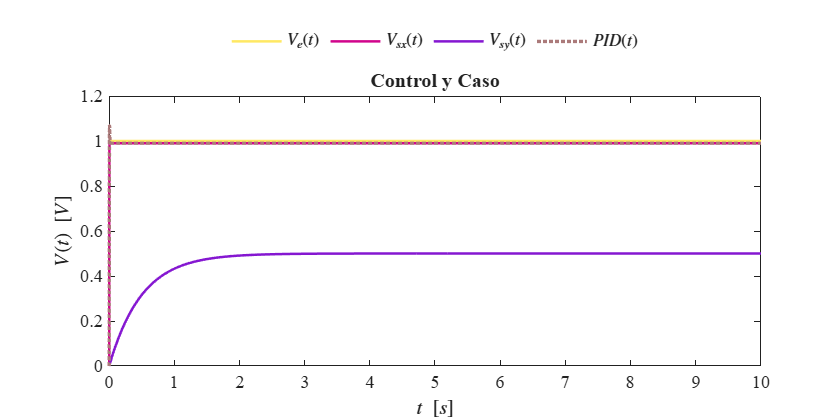

plotsignals(x.t, x.Ve, x.Vsx, x.Vsy, x.PID, 'Control y Caso')

## Función: Respuestas de la simulación

function plotsignals(t, Ve, Vsx, Vsy, PID, nombre)
set(figure(),'color','w')
set(gcf,'units','inches','position',[1,1,7,3.5])
set(gca,'fontname','times new roman','fontsize',11)
hold on; grid off;box on;

clr1 = [255, 232, 99]/255;
clr2 = [209, 5, 140]/255;
clr3 = [133, 23, 209]/255;
clr4 = [171,122,122]/255;
order = [clr1; clr2; clr3;clr4];
colororder(order)

P = plot(t, Ve, '-', ...
    t, Vsx, '-', ...
    t, Vsy, '-', ...
    t, PID, ':', ...
    'LineWidth', 1.5);
set(P(4), 'LineWidth', 2)
L = legend('$V_e(t)$', ...
    '$V_{sx}(t)$', ...
    '$V_{sy}(t)$', ...
    '$PID(t)$');
set(L, 'Interpreter', 'Latex', ...
    'FontSize', 10, ...
    'Location', 'NorthOutside', ...
    'Box', 'Off', ...
    'Orientation', 'Horizontal');
xlabel('$t\ [s]$', 'Interpreter', 'Latex', 'FontSize', 11)
ylabel('$V(t)\ [V]$', 'Interpreter', 'Latex', 'FontSize', 11)
xlim([0, 10]);
xticks(0:1:10);
title(nombre)
set(gca, 'FontName', 'Times New Roman', 'FontSize', 11)
exportgraphics(gcf, 'Control_y_Caso.pdf', 'ContentType', 'vector')
end